## **In the Name of God**

# Wireless Communication

# `CA#1`

# **Alireza Javid**

# **810198375**

### **Section 1 : Path Loss & Shadowing**

First we define model parameters as below:

clear all
clc
close all
N = 1e5;
d0 = 10;
D = 1000;
n = 4;
P0_dBm = -30;
N0_dBm = -175;
B = 1e6;
rng(1);

Remember, we want our users distributed in a circle area. Thus, we define dx and dy for the coordinate of every user in Cartesian coordinates according to the given circle area. We should check the distance of our users to be less than D. In other words, we select the users who the below formula would be satisfied with.


$$\;$$

$$\textrm{distance}\;\textrm{of}\;\textrm{each}\;\textrm{user}=\sqrt{{\textrm{dx}}^2 +{\textrm{dy}}^2 }\le \;D$$


dx = d0 + (D-d0).*rand(N*1.3,1);
dy = d0 + (D-d0).*rand(N*1.3,1);
users_dis = sqrt(dx.^2 + dy.^2);
users_dis = users_dis(users_dis < D);
N = length(users_dis);

Now, using the cdfplot function and below formula we plot the CDF plot for the recieved signal power.


$$P_r^{\;\textrm{dBm}} =P_0^{\;\textrm{dBm}} -10n\;\log_{10} \left(\frac{d}{d_0 }\right)$$


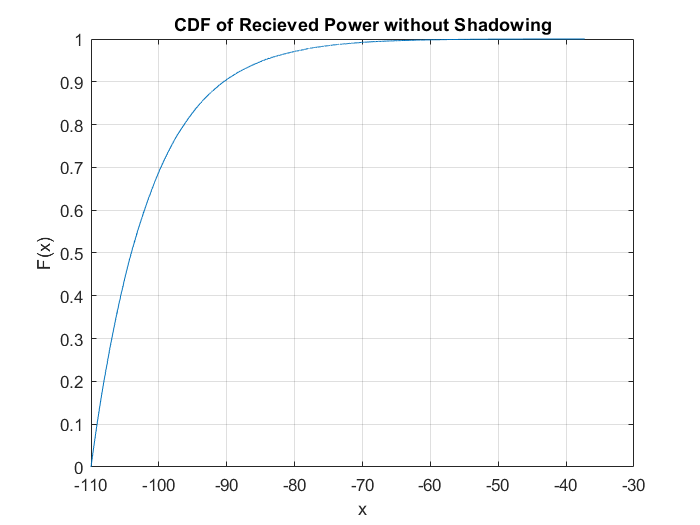

% users_dis = d0 + (D-d0).*rand(N,1);
Pr_dBm = P0_dBm -10*n*log10(users_dis/d0);
figure;
cdfplot(Pr_dBm);
title("CDF of Recieved Power without Shadowing")

For SNR of the recieved signal we have 


$$\textrm{SNR}=P_r^{\;\textrm{dBm}} -P_n^{\;\textrm{dBm}}$$


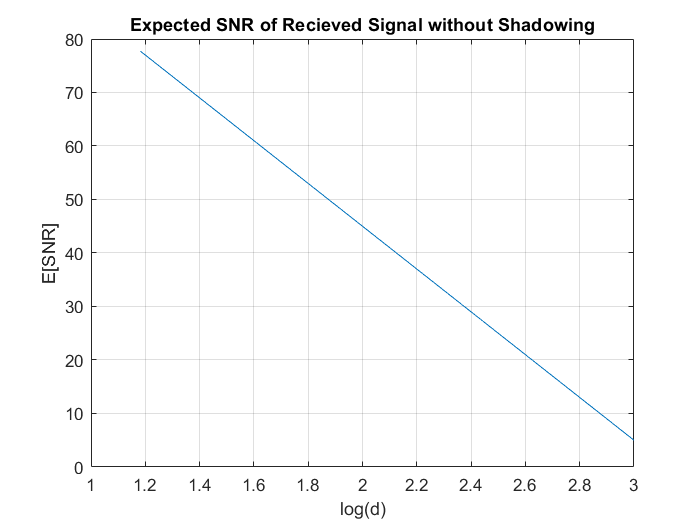

Pr_dBm_sorted = sort(Pr_dBm,'descend');
d_sorted = sort(users_dis);
SNR = Pr_dBm_sorted - (N0_dBm + 10*log10(B));
figure;
plot(log10(d_sorted), SNR)
title("Expected SNR of Recieved Signal without Shadowing")
xlabel("log(d)")
ylabel("E[SNR]")
grid on;

As we expected, SNR is decent with the increase in distance. (more accurately, SNR changes linearly with respect to log(d))

Now, it's time to add shadowing effect to our model as below:


$$P_r^{\;\textrm{dBm}} =P_0^{\;\textrm{dBm}} -10n\;\log_{10} \left(\frac{d}{d_0 }\right)+X^{\textrm{dB}}$$
                
$$X^{\textrm{dB}} ~N\left(0\;,\sigma^2 \right)\;,\;\;\;\;\;\sigma =5$$


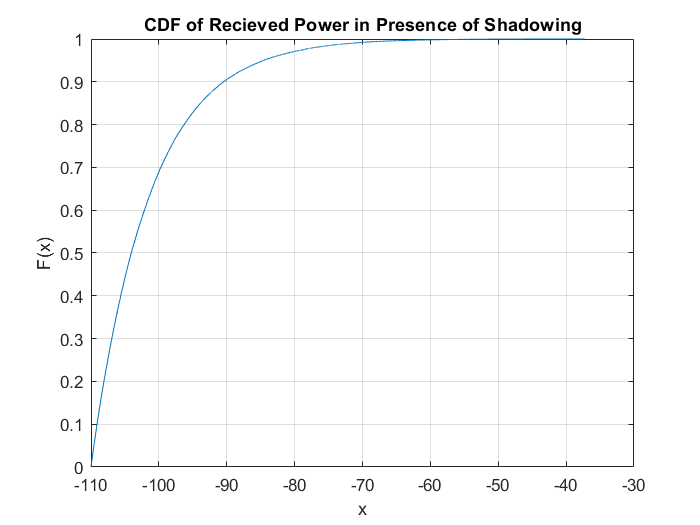

sigma = 5;
mean = 0;
X_dB = mean + sigma*randn(N,1);
Pr_dBm_shad = Pr_dBm_sorted + X_dB;
figure;
cdfplot(Pr_dBm);
title("CDF of Recieved Power in Presence of Shadowing")

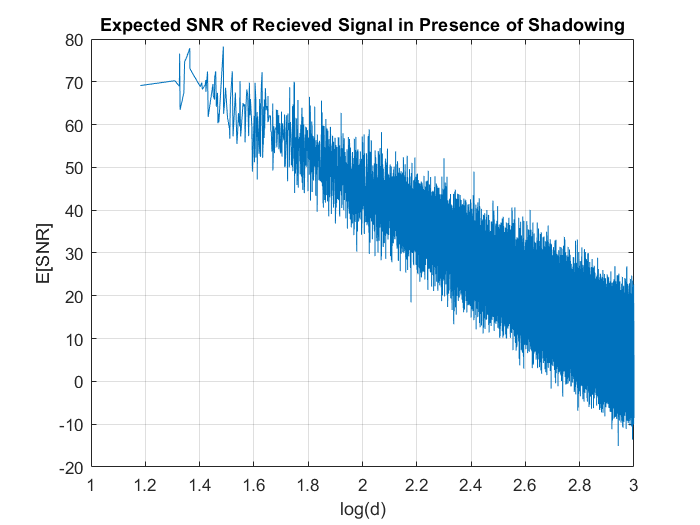

SNR_shad = Pr_dBm_shad - (N0_dBm + 10*log10(B));
figure;
plot(log10(d_sorted), SNR_shad)
title("Expected SNR of Recieved Signal in Presence of Shadowing")
xlabel("log(d)")
ylabel("E[SNR]")
grid on;

As the above plots demonstrate, adding the Shadowing effect to the model doesn't change the CDF plot. Conversely, the expected SNR plot follows an approximately linear pattern but unlike what was observed previously, this is not a smooth straight line due to the presence of bounces caused by shadowing, and at higher distances, the Shadowing effect becomes more effective. 

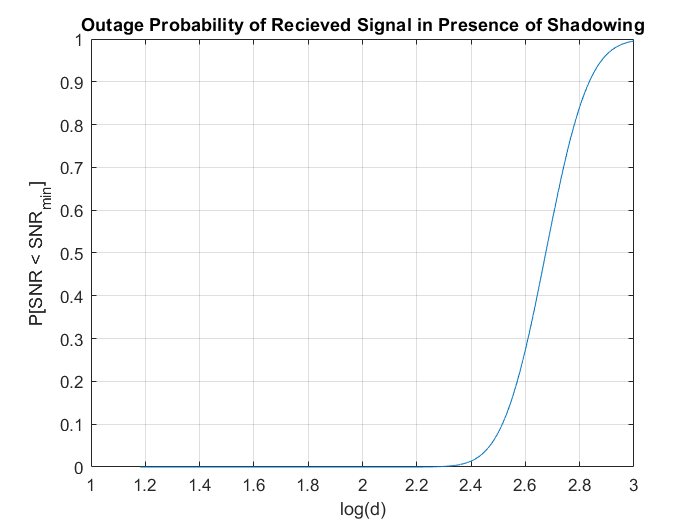

SNR_min = 18;
figure;
P_outag = 1 - qfunc((SNR_min -Pr_dBm_sorted ...
    + (N0_dBm + 10*log10(B)))/sigma);
plot(log10(d_sorted), P_outag)
title("Outage Probability of Recieved Signal in Presence of Shadowing")
xlabel("log(d)")
ylabel("P[SNR < SNR_{min}]")
grid on;

We can see after $\log \left(d\right)\approx 2\ldotp 4$, the outage probability highly increases.

We use below formulas to calculate the theoretical value.


$$C=Q(a)+\exp \left(\frac{2-2 a b}{b^2}\right) Q\left(\frac{2-a b}{b}\right)\\
a=\frac{P_{r, \min }-P_r(D)}{\sigma} \\
b=\frac{10 n \log _{10}(e)}{\sigma}
\\
P_r(D)=P_0-10 n \log _{10}\left(\frac{D}{d_0}\right)\\
S=\pi D^2 C$$


Pr_min = SNR_min + (N0_dBm + 10*log10(B));
Pr_D = P0_dBm - 10*n*log10(D/d0);
a = (Pr_min - Pr_D) / sigma;
b = 10*n*log10(exp(1))/ sigma;
C = qfunc(a) + exp((2 - 2*a*b)/ b^2) *qfunc((2 - a*b)/b);
S = pi*C*D^2;
fprintf("From theoretical relations C = " + num2str(C) + ...
    " and S = " + num2str(S));

From theoretical relations C = 0.2632 and S = 826877.5903

% covered_users = sum(SNR_shad > SNR_min);
% frac_covered_users = covered_users/length(SNR);
% S_sim = pi* frac_covered_users * D^2;
% fprintf("With sumilation C = " + num2str(frac_covered_users) + ...
%     " and S = " + num2str(S_sim) );
[~, last_SNR_index] = max(find(SNR > SNR_min));
fprintf("With sumilation C = " + num2str(d_sorted(last_SNR_index)^2/D^2) + ...
    " and S = " + num2str(pi * d_sorted(last_SNR_index)^2) );

With sumilation C = 0.22386 and S = 703280.8742

We can see the theoretical and simulation values are different due to the shadowing effect in theoretical part.

### **Section 2: **

In this part we want to simulate a wideband fading channel. After defining the parameters for calculating the gains we have:


$$r_{\textrm{in}-\textrm{phase}} ~N\left(0,\sigma^2 \right)$$
                
$$r_{\textrm{quardature}} ~N\left(0,\sigma^2 \right)$$
    

In above distributions we know that, $2\sigma^2$ is equals power gain. Thus, for impulse response of a rayleigh fading channel we have:


$$h\left(\tau \right)=\sum_{i=1} \alpha_i \;e^{-j\;\phi_i } \;\delta \left(\tau -\tau_i \right)$$
      

$\alpha_{i\;} =\sqrt{r_{\textrm{in}-\textrm{phase}}^2 +r_{\textrm{quardature}}^2 \;}$       ,     $\phi_i ~U\left(0,\frac{\pi }{2}\right)$

For calculating frequency response:


$$H\left(f\right)=\sum_{i=1} \alpha_i \;e^{-j\;\phi_i } \;e^{-j\;2\pi \;f\tau_i }$$


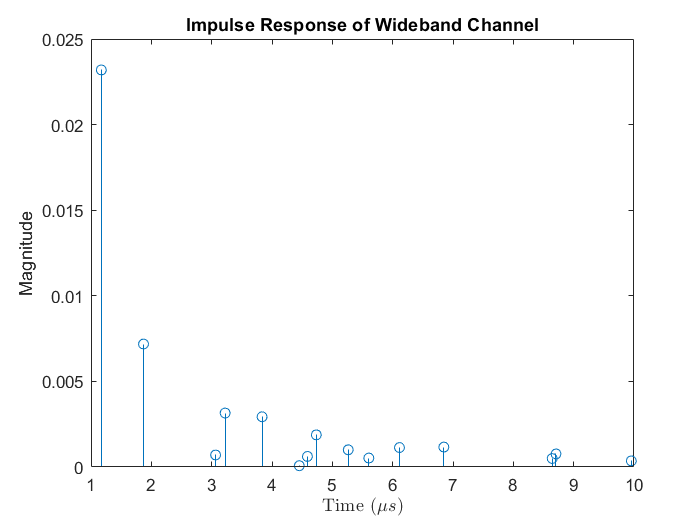

N = 15;
phi = 0.5*pi*rand(1, N);
tau = 1 + 9*rand(1, N);
sigma2 = 1e-3./tau.^4;
in_phase = sqrt(sigma2/2).*randn(1,N);
quadratic = sqrt(sigma2/2).*randn(1,N);
alpha = sqrt(in_phase.^2 + quadratic.^2);
% alpha = raylrnd(sqrt(sigma2/2));
h = alpha .* exp(1j*phi);

figure;
stem(tau, abs(h));
xlabel('Time ($\mu s$)','interpreter','latex', 'FontWeight','bold');
ylabel('Magnitude');
title('Impulse Response of Wideband Channel');

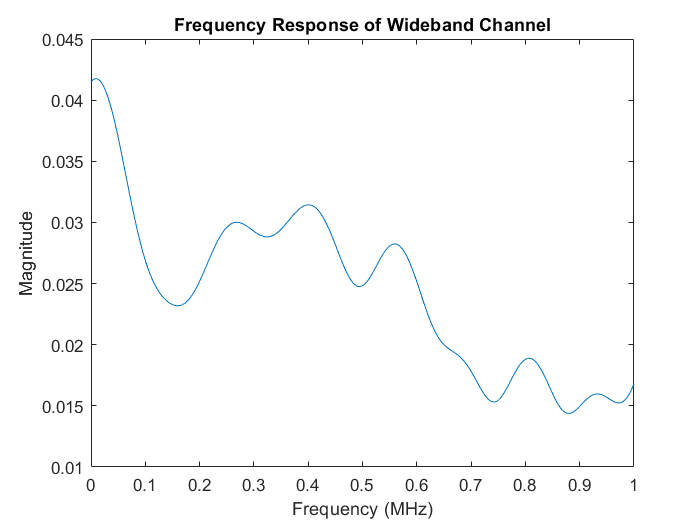


f = 0:1e6-1;
H = zeros(1, length(f));
for j=1:N
    H = H + alpha(j)*exp(-1i*phi(j))*exp(-1i*2*pi*f*tau(j)*1e-6);
end

figure;
plot(f/1e6, abs(H));
xlabel('Frequency (MHz)');
ylabel('Magnitude');
title('Frequency Response of Wideband Channel');

As we know, the gain value for each cluster follows the Rayleigh distribution (Z). The power value of each cluster is referred to as Z^2, and it follows an exponential distribution. The below graph shows how we can fit an exponential distribution to power values.

N = 15;
fc = 3e9;
v = 30;
lambda = 3e8/fc;
N_sim = 1e5;
powers = zeros(1,N_sim);
for i=1:N_sim
    phi = 0.5*pi*rand(1, N);
    delay = 1 + 9*rand(1, N);
    sigma2 = 1e-3./delay.^4;
    freq_D = v/lambda * cos(phi);
    phase_D = 2*pi*freq_D.*delay*1e-6;
    in_phase = sqrt(sigma2/2).*randn(1,N);
    quadratic = sqrt(sigma2/2).*randn(1,N);
    alpha = sqrt(in_phase.^2 + quadratic.^2);
    h = alpha .* exp(-1j*2*pi*fc.*delay*1e-6 + 1j*phase_D);
    powers(i) = sum(abs(h).^2);
end
clear mean
fprintf("Power mean value is " + num2str(mean(powers)));

Power mean value is 0.000555

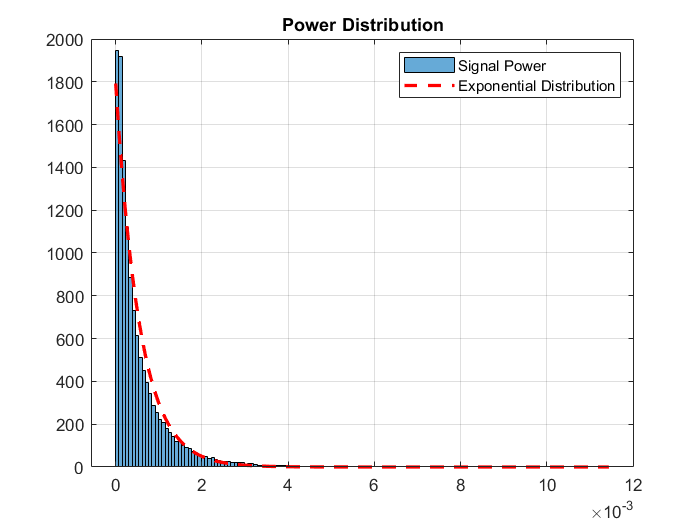

bins=150;
%plot power with corresponding exponential distribution
figure;
histogram(powers,bins,'Normalization','pdf');
pow_dist=fitdist(powers','Exponential');
pow_x=linspace(0,max(powers),bins);
pow_y=pdf(pow_dist,pow_x);
hold on;
plot(pow_x,pow_y,'r--','LineWidth',2);
grid on;
legend('Signal Power', 'Exponential Distribution');
title('Power Distribution');

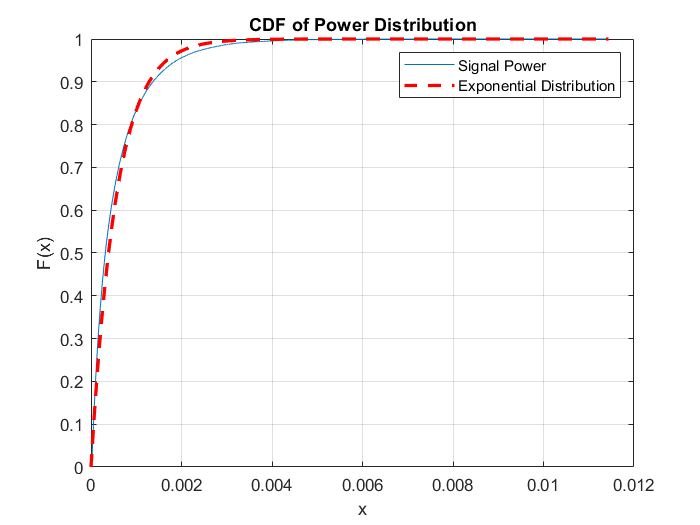

figure;
cdfplot(powers)
hold on
plot(pow_x, cdf(pow_dist,pow_x), 'r--','LineWidth',2)
grid on;
legend('Signal Power', 'Exponential Distribution');
title('CDF of Power Distribution');